# Dependencia

Para determinar si una correlación es significativa, ocupamos lo que se conoce como **coeficiente de determinación:**


$$\text{Coeficiente}=\rho^2$$


Si por ejemplo la correlación resulta ser 0,7, sólo el 49% de la variabilidad es compartida entre las dos series.

Por el contrario, es posible ocupar $1-\rho^2$ como un **parámetro de no deternimación**: el porcentaje de variabilidad **no** explicada.

# Significancia Estadística

El método más simple para corroborar que el coeficiente de correlación sea significativo es ocupando el **Test de Student**, para ello necesitaremos calcular lo siguiente:


$$T_c=\frac{\rho\sqrt{N-2}}{\sqrt{1-\rho^2}}$$


Donde N es el número de datos de una de las series, y N-2 son los grados de libertad.


$$S=\frac{\rho}{T_c}$$


#### ¿Cómo ocupamos la tabla T de Student?

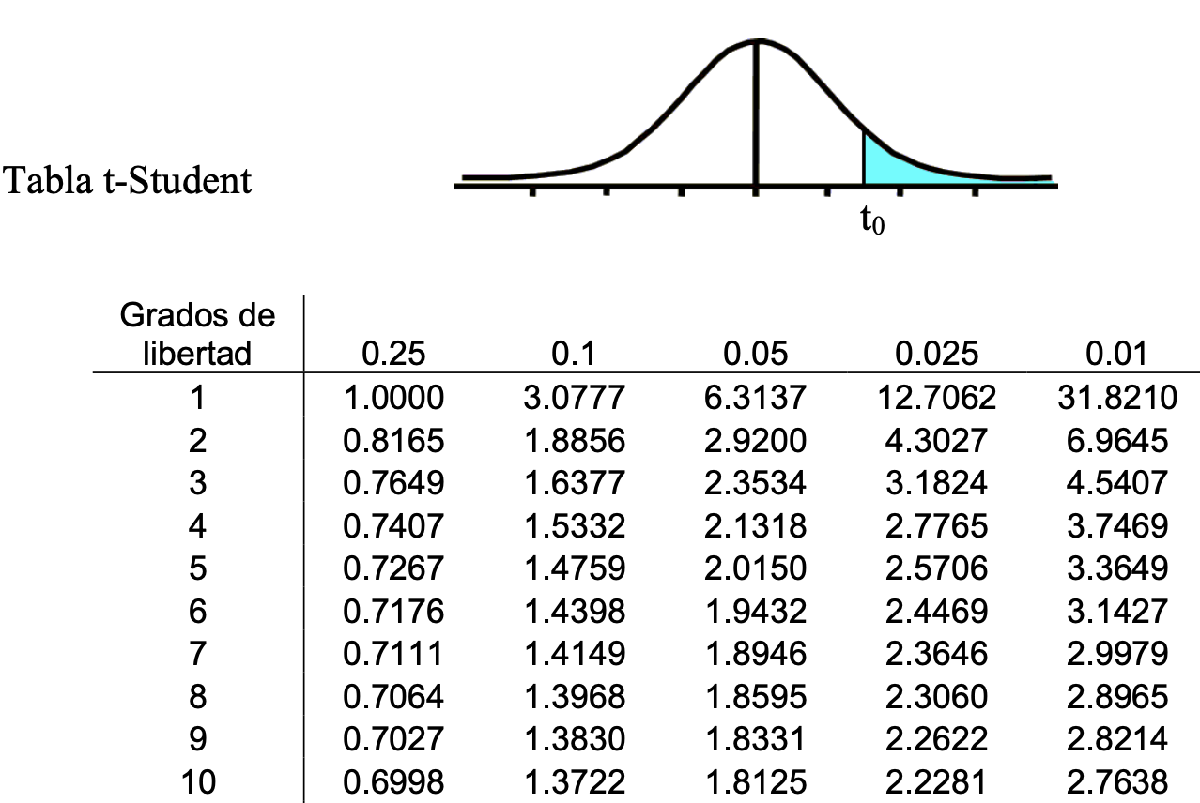

La columna izquierda nos indican los grados de libertad que tenemos, y la primera fila contiene los valores de **alfa/2**, donde,

$\alpha = \text{Nivel de significación}$ Se ocupa para los niveles de confianza


$$100*(1 - \alpha)\%=\text{Nivel de confianza}$$


*Ejemplo: ¿A cuál columna corresponde un nivel de confianza de un 95%?*

$100\cdot(1-\alpha)=95
\\
\alpha=0.05
\\
\frac{\alpha}{2}=0.025$ ---> *A la cuarta columna*

**Hay que comparar el ****VALOR ABSOLUTO**** de T calculado con los valores que aparecen en la tabla. **

- Si | `T_c`| es **mayor** al valor T de la tabla, la correlación es significativa

- Si | `T_c` | es **menor o igual** al valor T de la tabla, la correlación **no** es significativa

# Ejercicios

### Volvemos a ocupar los mismos datos de la práctica pasada (lunes 10) y sus respectivas correlaciones:

clear all 
close all 
clc 

% datos mensuales; 2003 a 2013
n34=importdata('N34.mat'); % niño 34 
calor=importdata('CALOR.mat'); % calor contenido en los primeros 700m desde la sup del mar
swl=importdata('swl.mat'); % nivel del mar promedio global

% Coeficientes de correlación
a= corr(n34(:,2),calor(:,2)); 
b= corr(n34(:,2),swl(:,2));
c= corr(calor(:,2),swl(:,2));

### Para cada una de ellas calcular T, y para un nivel de confianza de 98% verificar si la correlación es significativa

N=length(n34); % las tres series tienen el mismo largo, podemos usar cualquiera

t_a=a*sqrt((N-2)/(1-a^2));
t_b=b*sqrt((N-2)/(1-b^2));
t_c=c*sqrt((N-2)/(1-c^2));

% Alfa/2 es igual a 0.01, se ocupa la quinta columna de la imagen
% Respuesta, solo la tercera correlación es significativa (c) = 7.733
% Las otras dos tienen un valor absoluto menor al valor de la tabla

### **Calcular S para los tres casos**

s_a=a/t_a;
s_b=b/t_b;
s_c=c/t_c;

### Trabajamos con los mismos datos de calor, pero ahora ordenados en una matriz de 13 columnas (años 1955-2013)

calor2=importdata('CALOR_M_19552014.dat');

### Graficamos una serie de tiempo de sólo los meses de junio y diciembre:

figure % Recordar poner plots bonitoss
plot(calor2(:,1),calor2(:,7),'linewidth',2) % Línea de ancho dos
hold on
plot(calor2(:,1),calor2(:,13),'linewidth',2)
legend('Junio','Diciembre','Location','best') % leyenda no tapa los datos
xlabel('Años','FontSize',15,'FontWeight','bold')
ylabel('Calor','FontSize',15,'FontWeight','bold')
title('Calor contenido en los primeros 700 m del mar','FontSize',16)
grid minor
xlim tight % No quedan espacios en blanco

**Calculamos la correlación, T y S:**

rho=corr(calor2(:,7),calor2(:,13));
t_c=rho*sqrt((length(calor2)-2)/(1-rho^2));
s=rho/t_c;

**¿Para qué nivel de confianza la correlación es significativa?**

Recordar que tenemos 57 grados de libertad, buscamos en la tabla y vemos que todos los valores son inferiores a t_c

*El nivel de confianza tiende a un 100%*

**Repetir los dos ejercicios anteriores, pero ahora con las series sin tendencia, ¿qué ocurrió?**

figure % Graficamos
plot(calor2(:,1),detrend(calor2(:,7)),'linewidth',2)
hold on
plot(calor2(:,1),detrend(calor2(:,13)),'linewidth',2)
legend('Junio','Diciembre','Location','best')
xlabel('Años','FontSize',15,'FontWeight','bold')
ylabel('Calor','FontSize',15,'FontWeight','bold')
title('Serie de Tiempo sin tendencia','FontSize',16)
grid minor
xlim tight


% Calculamos rho, t y s:
rho_ST=corr(detrend(calor2(:,7)),detrend(calor2(:,13)));
t_ST=rho_ST*sqrt((length(calor2)-2)/(1-rho_ST^2));
s_ST=rho_ST/t_ST;

Al quitar la tendencia desaparece un factor que las dos series tenían en común (el calentamiento global), entonces la correlación decae.

A pesar de que la correlación ahora es menor, esta sigue siendo significativa para un intervalo de confianza mayor al 99%.

# Ejercicio Final (entre comillas, tarea)

### Hacer una función que entregue S y T para dos series de datos cualquiera.